## Ligninger

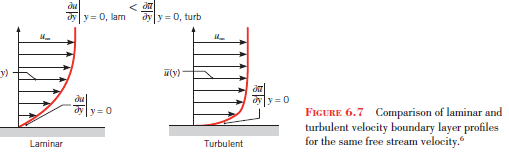

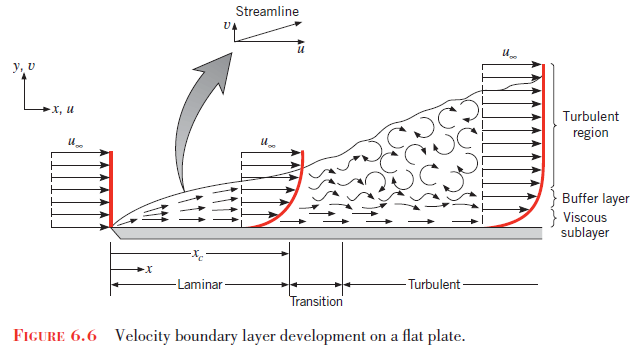

measure of turbulence inertial force / viscous force

a measure of the convection heat transfer occurring at the surface

$\alpha$ thermal diffusivity, m2/s;

$\nu$ kinematic viscosity, m2/s;

$\mu$ viscosity, kg/s ⋅ m

$k$ er thermal conductivity, W/m ⋅ K

## Opgaver

## Opgave 6.33

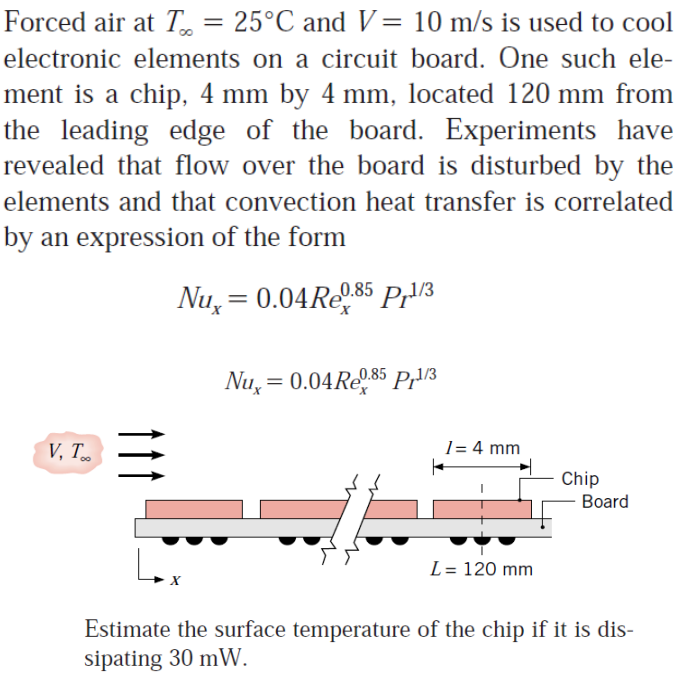

**Antagelser**

- Steady state

- ingen tab un eller på siden af chippen

% clear all
fluid = 'Air'

fluid = 'Air'

% Importer CoolProp-modul 
% https://www.youtube.com/watch?v=XvR10Fjph7U&t=434s
% [v, e] = pyversion; system([e, ' -m pip install --user -U CoolProp'])
CoolProp = py.importlib.import_module('CoolProp.CoolProp');
CoolProp = py.importlib.import_module('CoolProp.CoolProp');
P = 101325; % Pascal eller 1e5 %surface pressure
T_inf = 25 +273.15; %K
T_s = 42.2 +273.15; % overflade gæt
for i = 1:10
    fprintf('Interation %.d', i)
    T_film = (T_s + T_inf)/2 % film temperatur

Vi bruger film temperaturen til at finde vore matriale konstanter.

Dette er et gennemsnit imellem et kvalificerede gæt af overflade temperaturen og luft temperaturen. Når vi har udregnet overflade temperaturen 1 gang kan vi prøve igen med den nye overflde temperatur.

    c_p = CoolProp.PropsSI('Cpmass', 'P', P, 'T', T_film, fluid); %specificHeat_p
    k = CoolProp.PropsSI('conductivity', 'P', P, 'T', T_film, fluid); %thermalConductivity
    mu = CoolProp.PropsSI('viscosity', 'P', P, 'T', T_film, fluid); %Dynamisk viscositet
    rho = CoolProp.PropsSI('D', 'P', P, 'T', T_film, fluid); %Densitet
    V = 10; %m/s
    l = 4e-3; %m
    L = 0.120; %m
    % mu = 1.84e-5; % kg/(m·s) eller N⋅s/m2
    q = 30e-3; % W
    % c_p = 1007; %J/kg⋅K
    % k = 26.3e-3; %W/m⋅K varme conductivitet
    A = l * l;
    nu = mu/rho; %kinematisk viskositet %1.5577e-5;

    Re_x = V*L/nu
    Pr = c_p * mu / k

    Nu_x = 0.04*Re_x^(0.85) * Pr^(1/3)

    h = Nu_x/L * k;
    % R_tot = 1/(h*A)

    syms T_sym
    T = solve(q == (T_sym - T_inf) * h*A, T_sym);
    T_s = vpa(T - 273.15, 5)
    T_ss = T_s(i);
end

Interation 1

T_film = 306.7500

Re_x = 7.3232e+04

Pr = 0.7062

Nu_x = 486.0769

$$T\_s = 42.218$$

Interation 2

$$T\_film = 170.18402957514263107441365718842$$

Error using  () 
Conversion of MATLAB 'sym' to Python is not supported.

% q/(A*h) + 25 % 42.15


## Figurer og tabeller

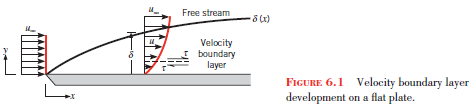

Behøves ikke udenad